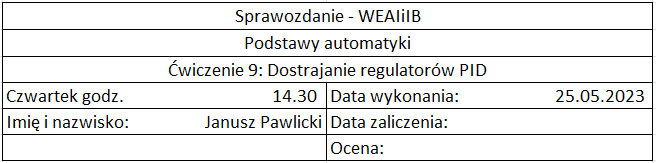

## 1. Wstęp

Metody nastaw regulatora PID:

- Zieglera Nicolsa - nastawy regulatora bez wcześniejszej znajomości modelu obiektu,

- Astroma-Haggunda - dobór nastaw korzystając z tych samych wzorów jak w przypadku metody Zieglera Nicolsa, ale bezpieczniejsza i szybsza

- metoda oparta o parametry odpowiedzi skokowej obiektu,

- 'Autotune' - automatyczny dobów nastaw w optymalny sposób.

## 2. Przebieg laboratorium

### 2.1 Ćwiczenie 1 - „klasyczny” eksperyment Zieglera - Nicholsa

% Regulator P
r = 2.5;
k = 1.18;
tau = 22;
T = 45;

kkr = 3.3;
Tosc = 75.781;

kp = 0.5 * kkr;
ki = 0;
kd = 0;

sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1522x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


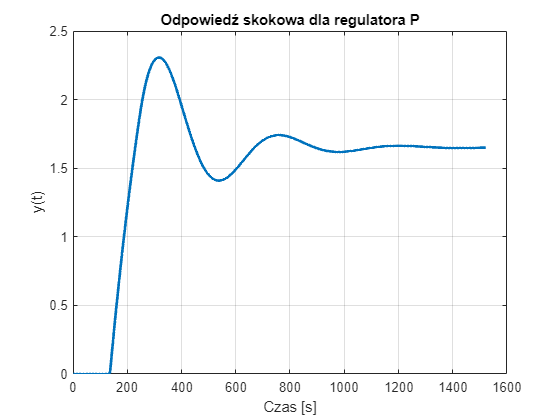


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa dla regulatora P');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

%Regulator PI

kp = 0.45 * kkr;
Ti = 0.85 * Tosc;

ki = kp/Ti;
kd = 0;

sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1521x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


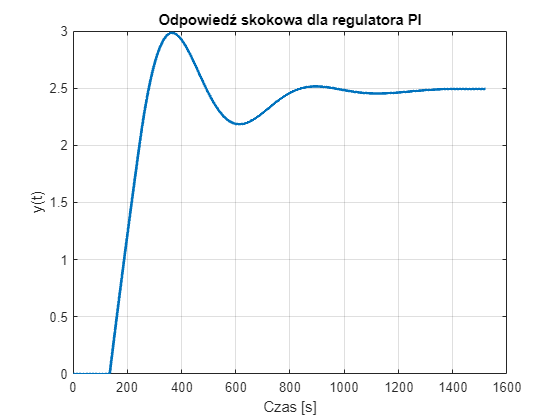


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa dla regulatora PI');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

% Regulator PID

kp = 0.6 * kkr;
Ti = 0.5 * Tosc;

ki = kp/Ti;
Td = 0.12 * Tosc;
kd = kp/Td;

sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1604x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


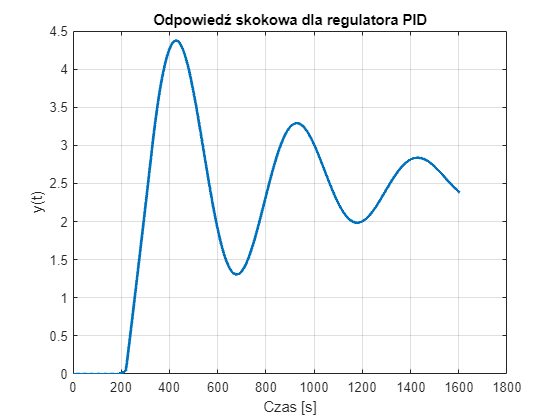


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa dla regulatora PID');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

### 2.2 Ćwiczenie 2 - Dostrajanie regulatora PID metodą Astroma-Hagglunda

u0 = 1;
u1 = 5;
u = u1 - u0;

Tosc1 = 82.036;
A = 1.818/2;
kkryt1 = (4*u)/(pi*A);

%Regulator P
kp = 0.5 * kkryt1;
ki = 0; 
kd = 0;

sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1521x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


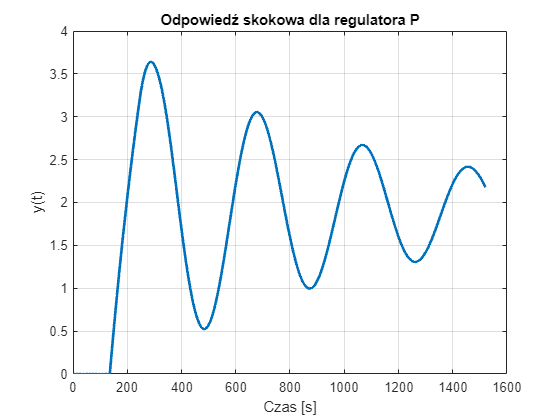


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa dla regulatora P');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

%Regulator PI
kp = 0.45 * kkryt1;
Ti = 0.85 * Tosc1;
ki = kp/Ti; 
kd = 0;

sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1521x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


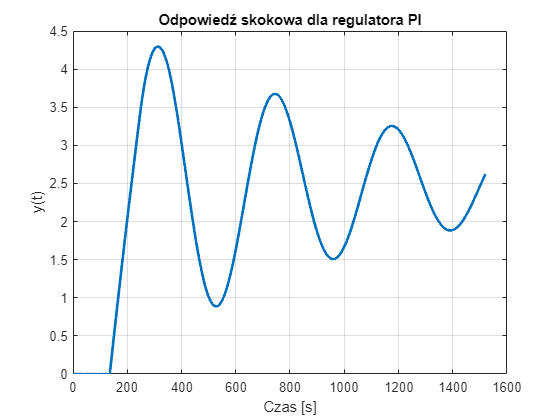


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa dla regulatora PI');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

%Regulator PID
kp = 0.6 * kkryt1;
Ti =0.12 * Tosc1;
ki = kp/Ti; 
Td = 0.12 * Tosc1;
kd = kp/Td;

sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1604x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


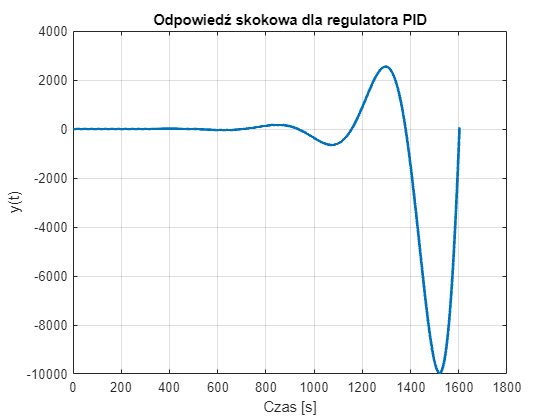


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa dla regulatora PID');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

### 2.3 Ćwiczenie 3 - Dostrajanie regulatora PID na podstawie parametrów transmitancji zastępczej 

kp = (0.95 * 45)/(22 * 1.18);
Ti = 2.4 * 22;
ki = kp/Ti;
Td = 0.4 * 22;
kd = kp/Td;
sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1598x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


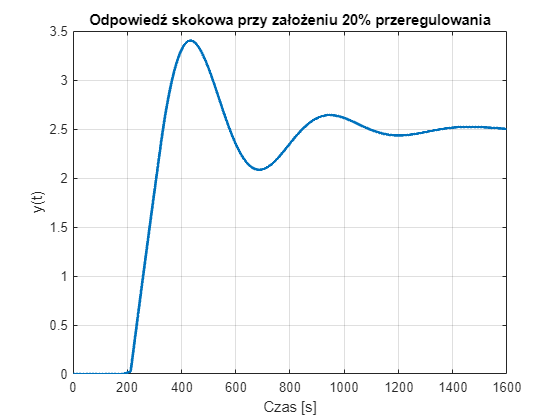


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa przy założeniu 20% przeregulowania');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

kp = (1.4 * 45)/(22 * 1.18);
Ti = 1.3 * 22;
ki = kp/Ti;
Td = 0.5 * 22;
kd = kp/Td;
sim('dostrajanie.slx')

ans =   Simulink.SimulationOutput:

                   tout: [1603x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


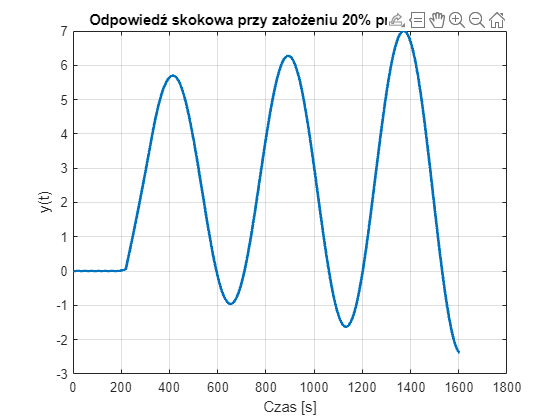


plot(ans.y.signals.values, 'LineWidth', 2);
title('Odpowiedź skokowa przy założeniu 50% przeregulowania');
ylabel('y(t)');
xlabel('Czas [s]')
grid on

### 2.4 Ćwiczenie 4 - Użycie funkcji „Autotune” dostępnej w środowisku SIMULINK

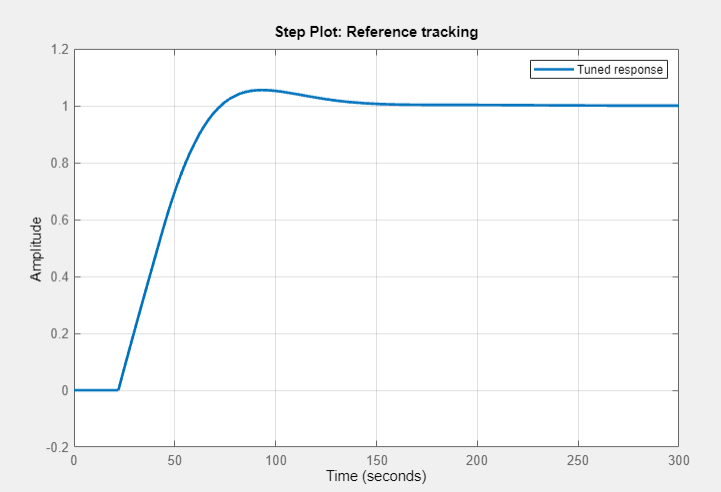

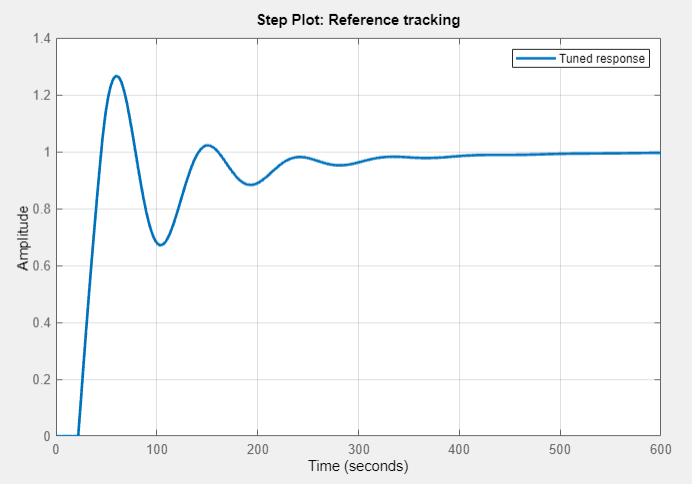

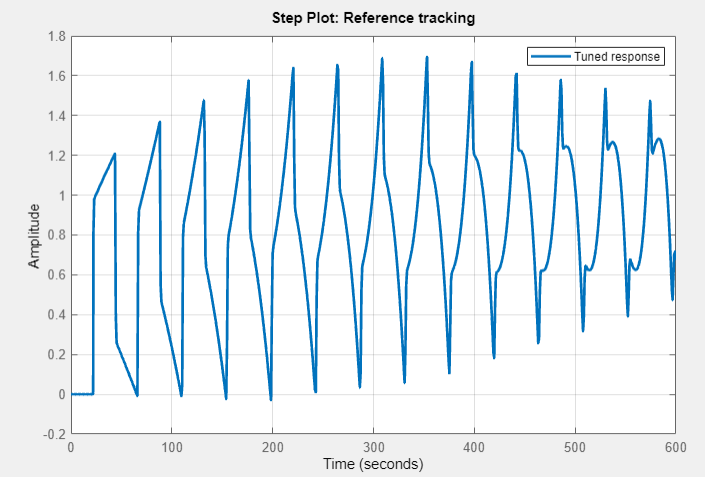

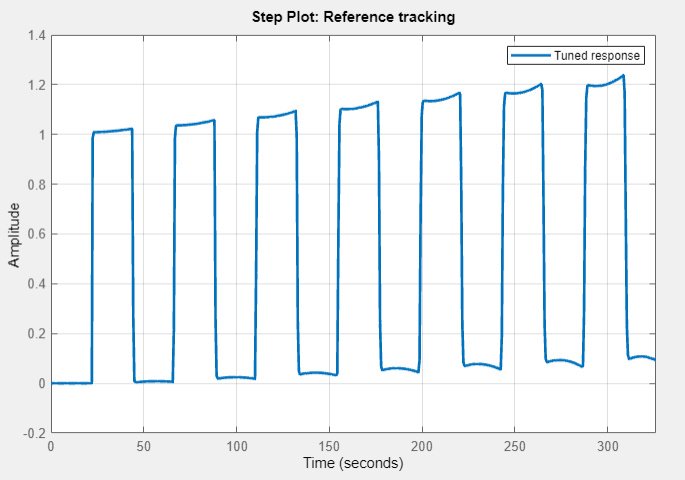

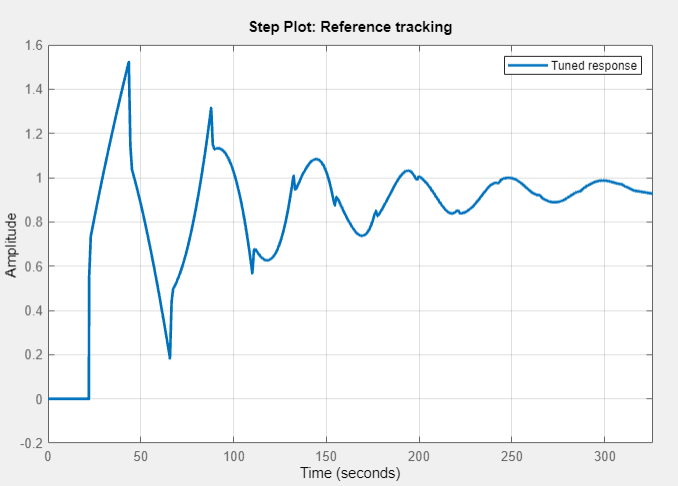

## 3 . Wnioski

Korzystając z metod Zieglera Nicolsa i Astroma-Hugglunda otrzymujemy niemal identyczne wyniki, jednak dal 3-członowego regulatora PID, nie jest taki "gładki". Korzystając z transmitacji widzimy, że nastway ustwaaidaj sie ansjzybciej , jeadna =k saprawa o nze oscyalcajca ssa najcbardziej widzoczne. Metoda autoanetu deaj enajeplepsze egaekty, onaa maiela male przegregulowania, as aczasy sa prorówannciami wja kw  cprzypadk uozosatałych metod.